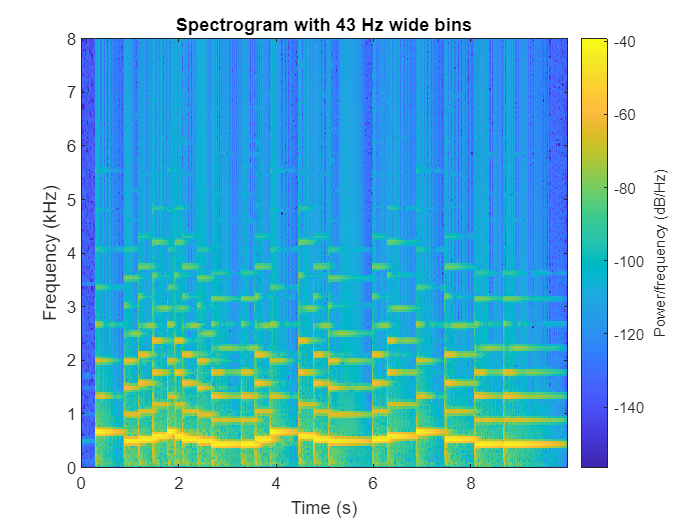

[x,fs] = audioread('piano.wav'); x = mean(x(1:10*fs,:),2);
figure; spectrogram(x,1024,0,1024,fs,'yaxis'); ylim([0,8]);
title('Spectrogram with 43 Hz wide bins')

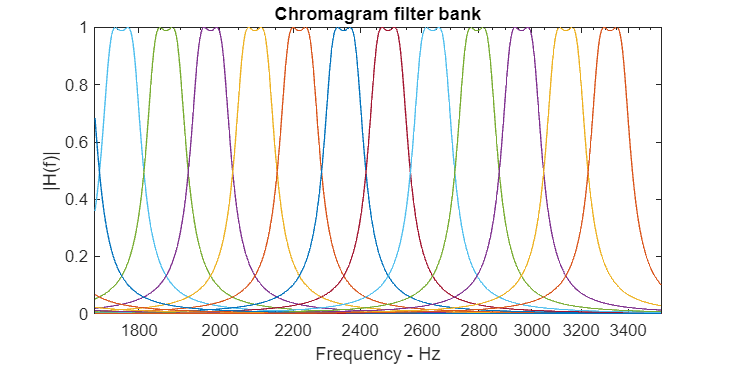

f = @(n) 440 * 2.^((n-49)/12);
figure;
filter_bank = {};
for i_note = 1:12
    for i_octave = 1:6
        note = 25+(i_note-1) + 12*(i_octave-1);
        [b,a] = ellip(2,0.1,80,f([note-0.2,note+0.2])./fs,'bandpass');
        [h,fh] = freqz(b,a,10000,fs);
        semilogx(fh,abs(h)); hold all;
        filter_bank{i_note,i_octave,1} = [b;a];
    end
end
xlim([1700,3550]); title('Chromagram filter bank')
xlabel('Frequency - Hz'); ylabel('|H(f)|');
set(gcf, 'Position', [0 0 600 300])

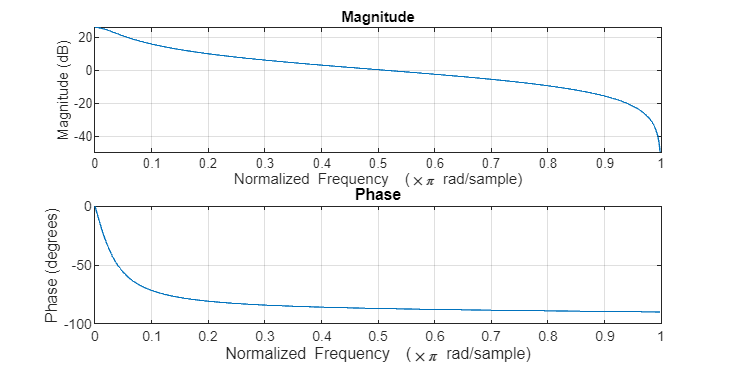

[b_smooth,a_smooth] = zp2tf(-1,0.9,1);
figure; freqz(b_smooth,a_smooth);
set(gcf, 'Position', [0 0 600 300])

chromagram = cell(12,1);
for i_note = 1:12
    chromagram{i_note} = zeros(size(x));
    for i_octave = 1:6
        b = filter_bank{i_note,i_octave}(1,:);
        a = filter_bank{i_note,i_octave}(2,:);
        y_sq = filter(b,a,x).^2;
        chromagram{i_note} = chromagram{i_note} + y_sq;
    end
    chromagram{i_note} = filter(b_smooth,a_smooth,chromagram{i_note});
    chromagram{i_note} = downsample(chromagram{i_note},6*12);
end
chromagram = cell2mat(chromagram')';

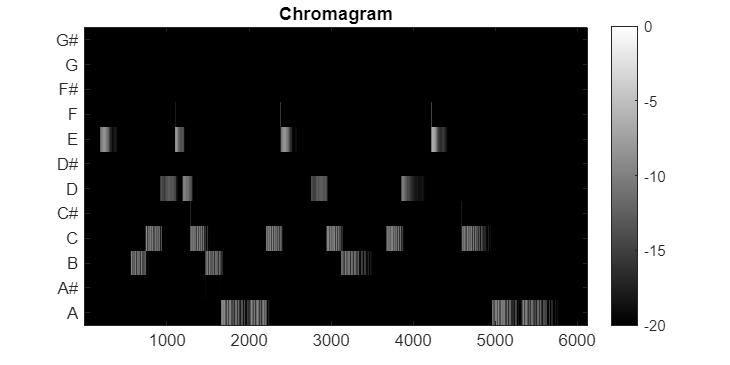

figure; imagesc(10*log10(chromagram)); axis xy; colormap gray;
colorbar; caxis([-20,0]); title('Chromagram')
set(gca,'ytick',1:12,'yticklabels',{'A','A#','B','C','C#','D','D#','E','F','F#','G','G#'});
set(gcf, 'Position', [0 0 600 300])

Notes played in the recording